# CRIBADO DE CALIDAD

## Cargar datos

T=readtable('metadata.csv')

T = 1570×3 table
          image           glaucoma    quality
    __________________    ________    _______

    {'image_0001.jpg'}       0           0   
    {'image_0002.jpg'}       0           0   
    {'image_0003.jpg'}       0           0   
    {'image_0004.jpg'}       0           0   
    {'image_0005.jpg'}       1           0   
    {'image_0006.jpg'}       0           0   
    {'image_0007.jpg'}       0           0   
    {'image_0008.jpg'}       0           0   
    {'image_0009.jpg'}       0           4   
    {'image_0010.jpg'}       1           0   
    {'image_0011.jpg'}       0           0   
    {'image_0012.jpg'}       0           0   
    {'image_0013.jpg'}       0           0   
    {'image_0014.jpg'}       0           0   
    {'image_0015.jpg'}       0           0   
    {'image_0016.jpg'}       1           0   


## Preprocesamiento- Separación entrenamiento/validación

T_no_revisada=table(T.image(T.quality==0), T.quality(T.quality==0), 'VariableNames', {'image', 'quality'})

T_no_revisada = 1261×2 table
          image           quality
    __________________    _______

    {'image_0001.jpg'}       0   
    {'image_0002.jpg'}       0   
    {'image_0003.jpg'}       0   
    {'image_0004.jpg'}       0   
    {'image_0005.jpg'}       0   
    {'image_0006.jpg'}       0   
    {'image_0007.jpg'}       0   
    {'image_0008.jpg'}       0   
    {'image_0010.jpg'}       0   
    {'image_0011.jpg'}       0   
    {'image_0012.jpg'}       0   
    {'image_0013.jpg'}       0   
    {'image_0014.jpg'}       0   
    {'image_0015.jpg'}       0   
    {'image_0016.jpg'}       0   
    {'image_0017.jpg'}       0   


T_revisada=table(T.image(T.quality~=0),T.quality(T.quality~=0) , 'VariableNames', {'image', 'quality'})

T_revisada = 309×2 table
          image           quality
    __________________    _______

    {'image_0009.jpg'}       4   
    {'image_0023.jpg'}       2   
    {'image_0032.jpg'}       4   
    {'image_0038.jpg'}       2   
    {'image_0040.jpg'}       2   
    {'image_0048.jpg'}       4   
    {'image_0065.jpg'}       1   
    {'image_0067.jpg'}       2   
    {'image_0068.jpg'}       3   
    {'image_0069.jpg'}       4   
    {'image_0078.jpg'}       4   
    {'image_0086.jpg'}       4   
    {'image_0094.jpg'}       4   
    {'image_0098.jpg'}       4   
    {'image_0099.jpg'}       1   
    {'image_0100.jpg'}       3   


%GUARDAR LAS DE BUENA CALIDAD (REVISADAS) EN UNA CARPETA
directorio_origen = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\BaseDeDatos_IMAGENES';
carpeta_destino = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\BuenaCalidad_BASE';

nombres_imagenes = T_revisada.image;
calidades = T_revisada.quality;

% Iterar sobre las imágenes y copiar las de calidad 4 a la carpeta destino
for i = 1:length(nombres_imagenes)
    nombre_imagen = nombres_imagenes{i};
    calidad = calidades(i);
    if calidad == 4
        origen = fullfile(directorio_origen, nombre_imagen);
        destino = fullfile(carpeta_destino, nombre_imagen);
        copyfile(origen, destino);
    end
end
T_revisada_BuenaCalidad=table(T.image(T.quality==4),T.glaucoma(T.quality==4) , 'VariableNames', {'image', 'glaucoma'})

T_revisada_BuenaCalidad = 149×2 table
          image           glaucoma
    __________________    ________

    {'image_0009.jpg'}       0    
    {'image_0032.jpg'}       1    
    {'image_0048.jpg'}       0    
    {'image_0069.jpg'}       0    
    {'image_0078.jpg'}       0    
    {'image_0086.jpg'}       1    
    {'image_0094.jpg'}       0    
    {'image_0098.jpg'}       0    
    {'image_0128.jpg'}       1    
    {'image_0142.jpg'}       0    
    {'image_0175.jpg'}       0    
    {'image_0176.jpg'}       0    
    {'image_0206.jpg'}       0    
    {'image_0207.jpg'}       1    
    {'image_0208.jpg'}       0    
    {'image_0235.jpg'}       0    


writetable(T_revisada_BuenaCalidad,'T_revisada_BuenaCalidad.csv')

## Pipeline del procesamiento de calidad

[M N]=size(T_revisada)

M = 309

N = 2

contraste=zeros(M,1);
entropia=zeros(M,1);
MSE=zeros(M,1);
sobel_max=zeros(M,1);
sobel_med=zeros(M,1);
sobel_std=zeros(M,1);
laplace_max=zeros(M,1);
laplace_med=zeros(M,1);
laplace_std=zeros(M,1);
rango_dinamico=zeros(M, 1);
varianza=zeros(M,1); 
min_intensity=zeros(M,1); 
max_intensity=zeros(M,1);
filtro_sobel_y = [-1 0 1; -2 0 2; -1 0 1];
filtro_sobel_x = [-1 -2 -1; 0 0 0; 1 2 1];

 %brisque
for i = 1:M
    I = imread(T_revisada.image{i});
    %if size(img, 3) == 3
    entropia(i) = entropy((I));
    I = double(rgb2gray(I));
   % end
    % Extraer características de imagenes
     
    
    Gx = imfilter(double(I), filtro_sobel_x, 'conv');
    Gy = imfilter(double(I), filtro_sobel_y, 'conv');
    G = Gx + Gy;
    absG = abs(Gx) + abs(Gy);

    Laplaziarra=[0 1 0; 1 -4 1; 0 1 0]; 
    L = imfilter(double(I),Laplaziarra, 'conv'); 
    % 
    % img_filtrada = medfilt2(double(I));
    % MSE(i) = immse(I, img_filtrada);

    % varianza(i) = var(I(:));
   
    contraste(i) = std2(I);  

    min_intensity(i)=min(I(:));
    max_intensity(i)=max(I(:));
    
    % sobel_max(i) = max(abs(absG(:))); 
    % sobel_med(i) = mean(abs(absG(:))); 
    % sobel_std(i) = std(abs(absG(:))); 
    % laplace_max(i)=max(abs(L(:)));
    laplace_med(i)=mean(abs(L(:)));
    % laplace_std(i)=std(abs(L(:)));

end
T_revisada=addvars(T_revisada,contraste, entropia, laplace_med,'NewVariableNames', {'Contraste', 'Entropia','Laplace_media'})

T_revisada = 309×5 table
          image           quality    Contraste    Entropia    Laplace_media
    __________________    _______    _________    ________    _____________

    {'image_0009.jpg'}       4        47.198        7.379         2.8394   
    {'image_0023.jpg'}       2        51.674       7.3154        0.59623   
    {'image_0032.jpg'}       4          48.1       6.5201         1.1611   
    {'image_0038.jpg'}       2        37.792       7.2489        0.42895   
    {'image_0040.jpg'}       2         45.61       6.6841         0.4247   
    {'image_0048.jpg'}       4        52.541       6.9146         1.2941   
    {'image_0065.jpg'}       1        5.7244       4.2585       0.098212   
    {'image_0067.jpg'}       2        43.085        7.008        0.43352   
    {'image_0068.jpg'}       3        76.818

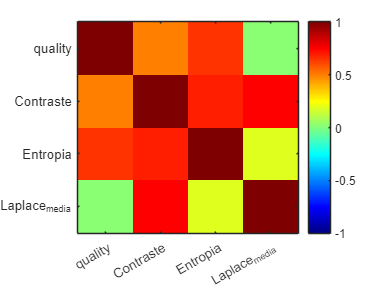

variables = T_revisada.Properties.VariableNames;
writetable(T_revisada,'T_revisadaCaracteristicas.csv')

X = T_revisada{:, 2:end};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:30);
xticklabels(variables(:,2:end));
yticks(1:30);
yticklabels(variables(:,2:end));
colormap(jet); colorbar;

# MODELOS CON CRIBADO DE CALIDAD

rng(4);

T=readtable('T_revisadaCaracteristicas.csv');
T.image=[]

T = 309×4 table
    quality    Contraste    Entropia    Laplace_media
    _______    _________    ________    _____________

       4        47.198        7.379         2.8394   
       2        51.674       7.3154        0.59623   
       4          48.1       6.5201         1.1611   
       2        37.792       7.2489        0.42895   
       2         45.61       6.6841         0.4247   
       4        52.541       6.9146         1.2941   
       1        5.7244       4.2585       0.098212   
       2        43.085        7.008        0.43352   
       3        76.818       7.2024         233.84   
       4        40.042       6.7133         1.3316   
       4         49.97       6.6746         1.2141   
       4        43.454       6.6346         1.3341   
       4        54.337       7.0074         1.1241   
       4        48.287       7.1124  

## Class imbalance

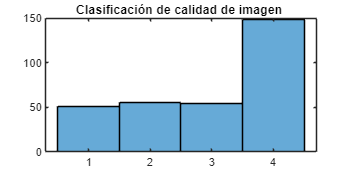


figure('Position', [0 0 350 170]);
histogram(T.quality)
title('Clasificación de calidad de imagen ')


T.quality = cellstr(num2str(T.quality));

% Convert the values in the 'Quality' column
for i = 1:height(T)
    if T.quality{i} == '1'
        T.quality{i} = 'Bajo contraste';
    elseif T.quality{i} == '2'
        T.quality{i} = 'Desenfoque';
   
    elseif T.quality{i} == '3'
        T.quality{i} = 'Ruido';
  
    elseif T.quality{i} == '4'
        T.quality{i} = 'Buena calidad';
    end
end

## Entrenamiento de modelo-KNN

### División de data

p = 0.2;
cv_out = cvpartition(T.quality, 'HoldOut', p, 'Stratify', true);
T_train = T(cv_out.training, :);
T_test  = T(cv_out.test, :);

k = 10;
cv_in = cvpartition(T_train.quality, 'KFold', k, 'Stratify', true);

% Create cross-validated KNN model
mdl_knn = fitcknn(T_train, 'quality', 'NumNeighbors', 3, 'CVPartition', cv_in);

% mdl_knn = fitcknn(T_train, 'quality', 'NumNeighbors', 3, 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_knn); % This row will print the mean error value. 

Estimate test performance

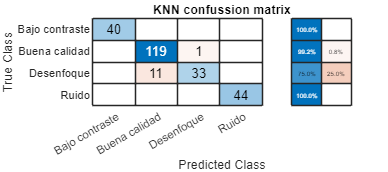

% mdl_loss = kfoldLoss(mdl_knn, 'Mode', 'Individual'); %This row will compute the Loss for each Cross-Validation fold. This is interesting for the final comparisons. 
Y_pred = kfoldPredict(mdl_knn);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = table;
results = [results; table("Knn", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.quality, Y_pred, 'RowSummary','row-normalized')
title('KNN confussion matrix');

## Entrenamiento de modelo-Classification Trees

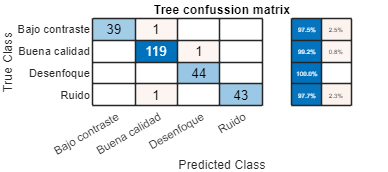

mdl_tree = fitctree(T_train, 'quality', 'CVPartition', cv_in);

mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

accuracy = sum(strcmp(Y_pred,T_train.quality)) / height(T_train);
results = [results; table("Tree", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.quality, Y_pred, 'RowSummary','row-normalized')
title('Tree confussion matrix');

## Entrenamiento de modelo-Naive Bayes

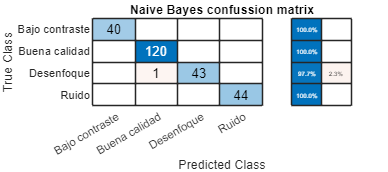

mdl_NB = fitcnb(T_train, 'quality','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_NB);
Y_pred = kfoldPredict(mdl_NB);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("Naive_bayes", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];
figure('Position', [0 0 450 200]);
confusionchart(T_train.quality, Y_pred, 'RowSummary','row-normalized')
title('Naive Bayes confussion matrix');

## Entrenamiento de modelo-Discriminant Analysis

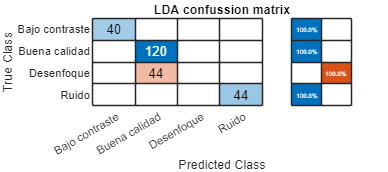

mdl_lda = fitcdiscr(T_train, 'quality','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_lda);
Y_pred = kfoldPredict(mdl_lda);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("LDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.quality, Y_pred, 'RowSummary','row-normalized')
title('LDA confussion matrix');

- To be different: Quadratic Discriminant Analysis (QDA)

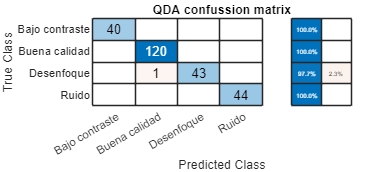

mdl_qda = fitcdiscr(T_train, 'quality','DiscrimType','quadratic','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_qda);
Y_pred = kfoldPredict(mdl_qda);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("QDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.quality, Y_pred, 'RowSummary','row-normalized')
title('QDA confussion matrix');

## Entrenamiento de modelo-SVM

mdl_svm = fitcecoc(T_train, 'quality','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);
Y_pred = kfoldPredict(mdl_svm);

accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("SVM", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

results

results = 6×3 table
        model          loss       accuracy
    _____________    _________    ________

    "Knn"             0.048387    0.95161 
    "Tree"            0.012097     0.9879 
    "Naive_bayes"    0.0040323    0.99597 
    "LDA"              0.17742    0.82258 
    "QDA"            0.0040323    0.99597 
    "SVM"                    0          1 


[~, best_model] = max(results.accuracy);
results(best_model, :)

ans = 1×3 table
    model    loss    accuracy
    _____    ____    ________

    "SVM"     0         1    


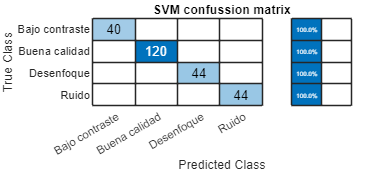


figure('Position', [0 0 450 200]);
confusionchart(T_train.quality, Y_pred, 'RowSummary','row-normalized')
title('SVM confussion matrix');

## Final model testing

mdl_final = fitcecoc(T_train, 'quality');
Y_pred = predict(mdl_final, T_test);

loss_final = loss(mdl_final, T_test)

loss_final = 0.0161

accuracy_final = sum(strcmp(Y_pred, T_test.quality)) / height(T_test.quality)

accuracy_final = 0.9836

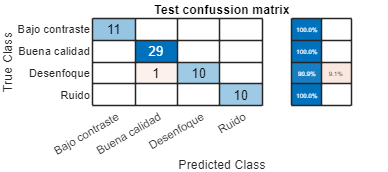



figure('Position', [0 0 450 200]);
confusionchart(T_test.quality, Y_pred, 'RowSummary','row-normalized')
title('Test confussion matrix');

# MODELO TEST

[M N]=size(T_no_revisada)

M = 1261

N = 2

contraste=zeros(M,1);
entropia=zeros(M,1);
laplace_med=zeros(M,1);
for i = 1:M
    I = imread(T_no_revisada.image{i});

    entropia(i) = entropy((I));
    I = double(rgb2gray(I));
    Laplaziarra=[0 1 0; 1 -4 1; 0 1 0]; 
    L = imfilter(double(I),Laplaziarra, 'conv'); 
    contraste(i) = std2(I);  
    min_intensity(i)=min(I(:));
    max_intensity(i)=max(I(:));
    laplace_med(i)=mean(abs(L(:)));
end
T_no_revisada=addvars(T_no_revisada,contraste, entropia, laplace_med,'NewVariableNames', {'Contraste', 'Entropia','Laplace_media'})

T_no_revisada = 1261×5 table
          image           quality    Contraste    Entropia    Laplace_media
    __________________    _______    _________    ________    _____________

    {'image_0001.jpg'}       0        47.479       6.5563         1.0352   
    {'image_0002.jpg'}       0        42.651       6.6329         1.1202   
    {'image_0003.jpg'}       0        42.894       7.0445         1.3517   
    {'image_0004.jpg'}       0        39.516       6.6714         1.2641   
    {'image_0005.jpg'}       0        46.796       7.0464         1.1234   
    {'image_0006.jpg'}       0        44.489       7.0967        0.44634   
    {'image_0007.jpg'}       0        45.702       6.0976        0.98142   
    {'image_0008.jpg'}       0         41.42       7.4417         2.7638   
    {'image_0010.jpg'}       0        51

variables = T_no_revisada.Properties.VariableNames;
writetable(T_no_revisada,'T_no_revisadaCaracteristicas.csv')


rng(4);
T_norevisada=readtable('T_no_revisadaCaracteristicas.csv');
Imagen=T_norevisada.image

Imagen = 1261×1 cell array
    {'image_0001.jpg'}
    {'image_0002.jpg'}
    {'image_0003.jpg'}
    {'image_0004.jpg'}
    {'image_0005.jpg'}
    {'image_0006.jpg'}
    {'image_0007.jpg'}
    {'image_0008.jpg'}
    {'image_0010.jpg'}
    {'image_0011.jpg'}
    {'image_0012.jpg'}
    {'image_0013.jpg'}
    {'image_0014.jpg'}
    {'image_0015.jpg'}
    {'image_0016.jpg'}
    {'image_0017.jpg'}
    {'image_0018.jpg'}
    {'image_0019.jpg'}
    {'image_0020.jpg'}
    {'image_0021.jpg'}
    {'image_0022.jpg'}
    {'image_0024.jpg'}
    {'image_0025.jpg'}
    {'image_0026.jpg'}
    {'image_0027.jpg'}
    {'image_0028.jpg'}
    {'image_0029.jpg'}
    {'image_0030.jpg'}
    {'image_0031.jpg'}
    {'image_0033.jpg'}


T_norevisada.image=[]

T_norevisada = 1261×4 table
    quality    Contraste    Entropia    Laplace_media
    _______    _________    ________    _____________

       0        47.479       6.5563         1.0352   
       0        42.651       6.6329         1.1202   
       0        42.894       7.0445         1.3517   
       0        39.516       6.6714         1.2641   
       0        46.796       7.0464         1.1234   
       0        44.489       7.0967        0.44634   
       0        45.702       6.0976        0.98142   
       0         41.42       7.4417         2.7638   
       0        51.378       7.1495         1.2379   
       0        42.921       7.3953         1.8127   
       0        43.987       6.9269         1.3332   
       0        42.809       7.4556         1.5534   
       0        44.878        6.843         1.3377   
       0        42.064   


T_norevisada.quality = cellstr(num2str(T_norevisada.quality));

% Convert the values in the 'Quality' column
for i = 1:height(T_norevisada)
    if T_norevisada.quality{i} == '1'
        T_norevisada.quality{i} = 'Bajo contraste';
    elseif T_norevisada.quality{i} == '2'
        T_norevisada.quality{i} = 'Desenfoque';
   
    elseif T_norevisada.quality{i} == '3'
        T_norevisada.quality{i} = 'Ruido';
  
    elseif T_norevisada.quality{i} == '4'
        T_norevisada.quality{i} = 'Buena calidad';
    end
end

Y_pred_1 = predict(mdl_final, T_norevisada)

Y_pred_1 = 1261×1 cell array
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Desenfoque'   }
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}
    {'Buena calidad'}



T=table(Imagen,Y_pred_1, 'VariableNames',{'Imagen', 'Prediccion'})

T = 1261×2 table
          Imagen             Prediccion    
    __________________    _________________

    {'image_0001.jpg'}    {'Buena calidad'}
    {'image_0002.jpg'}    {'Buena calidad'}
    {'image_0003.jpg'}    {'Buena calidad'}
    {'image_0004.jpg'}    {'Buena calidad'}
    {'image_0005.jpg'}    {'Buena calidad'}
    {'image_0006.jpg'}    {'Desenfoque'   }
    {'image_0007.jpg'}    {'Buena calidad'}
    {'image_0008.jpg'}    {'Buena calidad'}
    {'image_0010.jpg'}    {'Buena calidad'}
    {'image_0011.jpg'}    {'Buena calidad'}
    {'image_0012.jpg'}    {'Buena calidad'}
    {'image_0013.jpg'}    {'Buena calidad'}
    {'image_0014.jpg'}    {'Buena calidad'}
    {'image_0015.jpg'}    {'Buena calidad'}
    {'image_0016.jpg'}    {'Buena calidad'}
    {'image_0017.jpg'}    {'Buena calidad'}



buena_calidad=sum(Y_pred_1=="Buena calidad")

buena_calidad = 1230

ruido=sum(Y_pred_1=="Ruido")

ruido = 8

desenfoque=sum(Y_pred_1=="Desenfoque")

desenfoque = 6

bajo_contraste=sum(Y_pred_1=="Bajo contraste")

bajo_contraste = 17


[M N]=size(T)

M = 1261

N = 2

 
% for i = 1:M
%     if T.("Prediccion"){i}=="Ruido"
%        figure; 
%         I = imread(T.Imagen{i});
%         imshow(I)
%          title('Ruido');
%     elseif T.("Prediccion"){i}=="Bajo contraste"
%        figure; 
%         I = imread(T.Imagen{i});
%         imshow(I)
%         title('Bajo contraste');
%     elseif T.("Prediccion"){i}=="Desenfoque"
%         figure; 
%         I = imread(T.Imagen{i});
%         imshow(I)
%          title('Desenfoque');
%     end
% end


% for i = 1:M
%     if T.("Prediccion"){i}=="Buena calidad"
%        figure; 
%         I = imread(T.Imagen{i});
%         imshow(I)
%     end
% end
% 
% directorio_origen = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\BaseDeDatos_IMAGENES';
% 
% % Carpeta de destino para guardar las imágenes de buena calidad
% carpeta_destino_buenacalidad = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\BuenaCalidad_SVM';
% carpeta_destino_ruido='C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\Ruido_SVM';
% carpeta_destino_desenfoque='C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\Desenfoque_SVM';
% carpeta_destino_bajocontraste='C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\BajoContraste_SVM';
% 
% % Obtener nombres de las imágenes y sus predicciones
% nombres_imagenes = T.Imagen;
% predicciones = T.Prediccion;

% Iterar sobre las imágenes y copiar las de buena calidad a la carpeta destino
% for i = 1:length(nombres_imagenes)
%     nombre_imagen = nombres_imagenes{i};
%     prediccion = predicciones{i};
%     if strcmp(prediccion, 'Buena calidad')
%         origen = fullfile(directorio_origen, nombre_imagen);
%         destino = fullfile(carpeta_destino_buenacalidad, nombre_imagen);
%         copyfile(origen, destino);
% 
%     elseif strcmp(prediccion, 'Bajo contraste')
%         origen = fullfile(directorio_origen, nombre_imagen);
%         destino = fullfile(carpeta_destino_bajocontraste, nombre_imagen);
%         copyfile(origen, destino);
% 
%     elseif strcmp(prediccion, 'Ruido')
%             origen = fullfile(directorio_origen, nombre_imagen);
%             destino = fullfile(carpeta_destino_ruido, nombre_imagen);
%             copyfile(origen, destino);
% 
%     elseif strcmp(prediccion, 'Desenfoque')
%         origen = fullfile(directorio_origen, nombre_imagen);
%         destino = fullfile(carpeta_destino_desenfoque, nombre_imagen);
%         copyfile(origen, destino);
%     end
% 
% end


